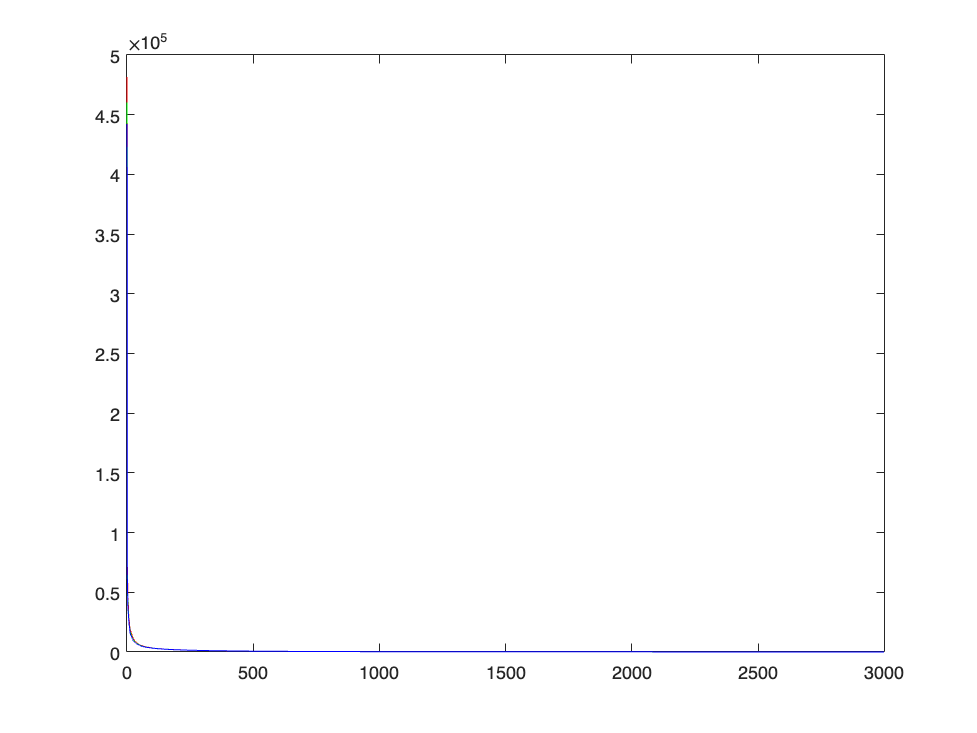

%importing class from macOS Desktop
class=imread('KakaoTalk_Photo_2023-04-27-20-40-29.jpeg');
A1=class(:,:,1);A2=class(:,:,2);A3=class(:,:,3);

%SVD decomposion
A1=double(A1);A2=double(A2);A3=double(A3);
[U1 S1 V1]=svd(A1);[U2 S2 V2]=svd(A2);[U3 S3 V3]=svd(A3);

%SV distribution
diagS1=diag(S1);diagS2=diag(S2);diagS3=diag(S3);
figure;plot(diagS1,'-r');hold on;plot(diagS2,'-g');plot(diagS3,'-b');

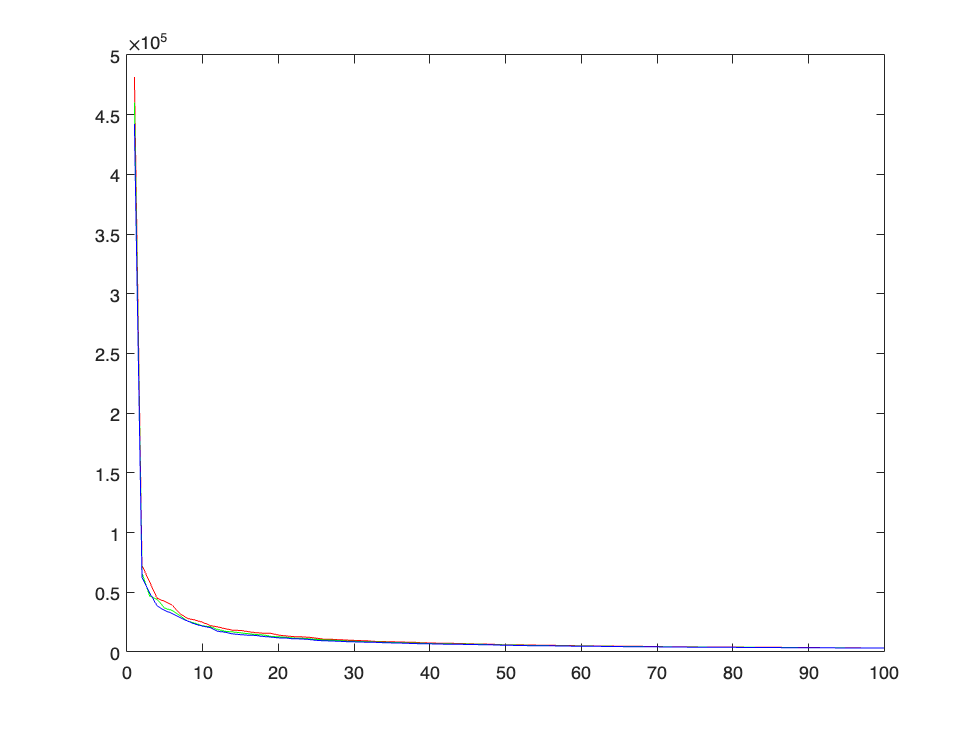

figure;plot(diagS1,'-r');hold on;plot(diagS2,'-g');plot(diagS3,'-b');xlim([0 100]);


%Compressing class at extreme compression:
[k1 k2 k3]=compression(diagS1,diagS2,diagS3,1e03);
classapprox(:,:,1)=U1(:,1:k1)*S1(1:k1,1:k1)*V1(:,1:k1)';
classapprox(:,:,2)=U2(:,1:k2)*S2(1:k2,1:k2)*V2(:,1:k2)';
classapprox(:,:,3)=U3(:,1:k3)*S3(1:k3,1:k3)*V3(:,1:k3)';

%Showing the result
fprintf('The size of compressed doyeunjoo image is %f percent of original \ndoyeunjoo image',(k1/size(A1,1))*(k2/size(A2,1))*(k3/size(A3,1))*100)

The size of compressed doyeunjoo image is 0.175211 percent of original 
doyeunjoo image

classapprox=uint8(classapprox);

function [k1,k2,k3]=compression(diagS1,diagS2,diagS3,N)
    k1=1;k2=1;k3=1;
    while(diagS1(k1,1)>N)
        k1=k1+1;
    end
    while(diagS2(k2,1)>N)
        k2=k2+1;
    end
    while(diagS3(k3,1)>N)
        k3=k3+1;
    end
end